# Week 3 Assignment

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

## Introduction:

### Problem 1

Problem 1, of Robot Modeling and Control Second Edition by Spong et al.,gives two fixed frame rotation matrice. The first given rotation matrix describes the rotation of frame 2, $o_2$$x_2$$y_2$$z_2$, relative to frame 1, $o_1$$x_1$$y_1$$z_1$, $R_2^1$. The second given rotation matrix descirbes the rotation of frame 3, $o_3$$x_3$$y_3$$z_3$, relative to frame 1, $o_1$$x_1$$y_1$$z_1$, $R_3^1$. Figure 1 display the given rotation matrices for problem 1 


$$R_2^1 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & -\frac{\sqrt{3}}{2}\\
0 & \frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack$$
 
$$R_3^1 =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$$


**Figure 1**: given rotation matrices for problem 1 

The goal of problem 1 is to present the matrix product that will produce the rotation matrix that relates the transformation of frame 3,, to frame 2, $R_3^2$.This will be achieved by explicitly displaying and describing each step taken towards achieving the desired rotation matrix. This will involve not only showing the associated formulas but also displaying a figure that illustrates the described rotation. Once the rotation matrix equation is derived, random values will be produced for all angle variables and the appropriate matrix product will be calculated.

### Problem 2 

The objective of problem 2 is to present the homogeneous transformations, $H_1^0 ,H_2^0 ,H_3^0 \;\textrm{and}\;H_3^2$ for the diagram displayed in figure 2.14. This will be accomplished by showing all the steps and assocaited equations that were used in order to attain the final answer 

### 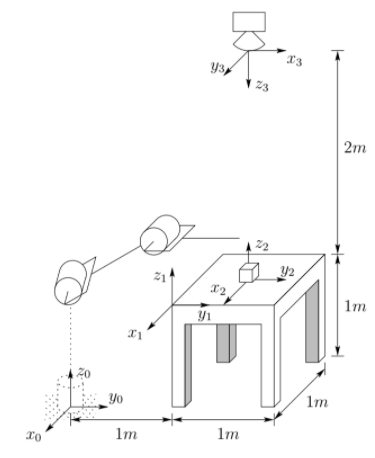

***Figure 2.14: ****Diagram for Problem 2-38*

### Problem 3

The objective of problem 3 present the homogeneous transformation matrix that relates frame 4 to frame 0. This will be accomplished by analyzing the robot diagram, figure 3, and showing all of the steps taken to obtain the matrix. Then I will draw the end effector path in response to varying joint angle inputs.

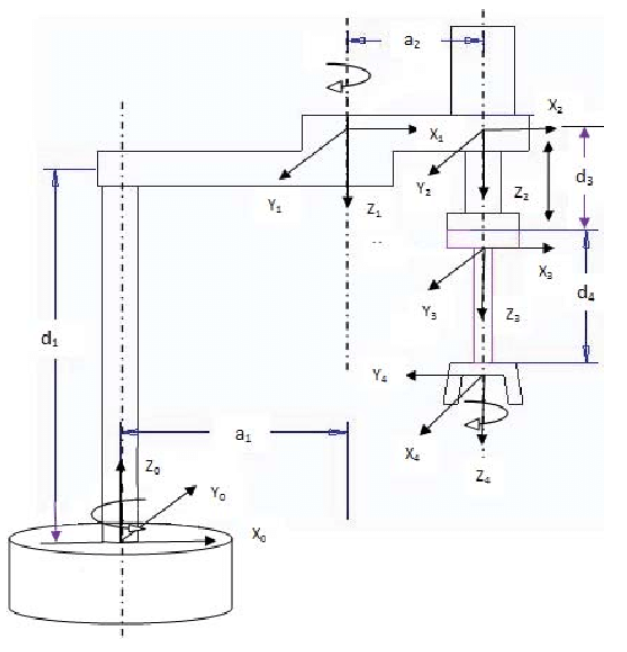

**Figure 3**: Robot diagram for problem 3

## Methods and Materials:

### Problem 1

#### Answer :


$$R_3^2 =R_1^2 R_3^1 =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
\frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\
\frac{1}{2} & -\frac{\sqrt{3}}{2} & 0
\end{array}\right\rbrack$$


Problem 1  deals with composition of rotation matrices, or the order in which successive rotation matrices should be multiplied to produce the the desired rotation matrix. The problem gave two rotation matrices, shown in figure 1. The first given rotation matrix describes the rotation of frame 2, $o_2$$x_2$$y_2$$z_2$, relative to frame 1, $o_1$$x_1$$y_1$$z_1$, $R_2^1$. The second given rotation matrix descirbes the rotation of frame 3, $o_3$$x_3$$y_3$$z_3$, relative to frame 1, $o_1$$x_1$$y_1$$z_1$, $R_3^1$. Given these two matrices, it is possible to find the rotation matrix that relates  the transformation of frame 3,, to frame 2, $R_3^2$. 

For this problem I will assume that the given rotation matrices descirbe current frame rotations. If the rotation is performed about a current coordinate frame axis then the previous multiplication should be post multiplied by the described current frame rotation.  Equation 2.22 from the textbook, describes the case where the second rotation,$R_2^1$ , is performed relative to the current frame, therefore the previous rotation, $R_1^0$, is post-multiplied by the second rotation. 

In order to attain the rotation matrix that relates  the transformation of frame 3 to frame 2, $R_3^2$, the rotation from frame 2 to 1, $R_1^2$, must be post multiplied by the rotation from frame 1 to 3,$R_3^1$. Equation 1, shows that $R_1^2$ is the transpose of $R_2^1$. Equation 2, shows the matrix product that produces the rotation from frame 2 to 3,$R_3^2$.

$R_1^2 ={R_2^1 }^T ={\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & -\frac{\sqrt{3}}{2}\\
0 & \frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack }^T =$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & \frac{\sqrt{3}}{2}\\
0 & -\frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack$                                                                                      (1)

$R_3^2 =R_1^2 R_3^1 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & \frac{\sqrt{3}}{2}\\
0 & -\frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
\frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\
\frac{1}{2} & -\frac{\sqrt{3}}{2} & 0
\end{array}\right\rbrack$                                                               (2)

### Problem 2 

#### Answer:


$$H_1^0 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 1\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_2^0 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & -\frac{1}{2}\\
0 & 1 & 0 & 1\ldotp 5\\
0 & 0 & 1 & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_3^0 =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & -\frac{1}{2}\\
1 & 0 & 0 & 1\ldotp 5\\
0 & 0 & -1 & 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_3^2 =H_0^2 \;H_3^0 =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
1 & 0 & 0 & 0\\
0 & 0 & -1 & 2\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Problem 2 involves rigid motion. Rigid motion is represents both orientation and position (1). Orientation is represented by the system's rotation matrix and position is represented by the systems position vector.  Homogeneous tranformation matrices are the matrix representation of rigid motion (1). Equation 2.66 in the textbook shows the equation for homogeneous tranformation matrices. 

The problem requires the homogeneous transformation matrices $H_1^0 ,H_2^0 ,H_3^0 \;\textrm{and}\;H_3^2$ to be calculated for the system shown in figure 2.14. The syststem is composed of a table that is located in  frame 1 $o_1$$x_1$$y_1$$z_1$, a cube located in frame 2 $o_2$$x_2$$y_2$$z_2$, a camera directly above the cube located in frame 3  $o_3$$x_3$$y_3$$z_3$, and a robot whose base is located in frame 0  $o_0$$x_0$$y_0$$z_0$. The matrix $H_1^0$, represents the transformations of frame 1 with respect to frame 0. The matrix$H_2^0$, represents the  transformations of frame 2 with respect to frame 0. The matrix$H_3^0$, represents the  transformations of frame 3 with respect to frame 0. The matrix $H_3^2$, represents the transformations of frame 3 with respect to frame 2. According to equation 2.66, in order to calculate a homogeneous tranformation matrix both the rotation matrix and position vector of that transformation are needed.  In order to calculate the homogeneous transformation matrix of frame 1 with respect to frame 0,$H_1^0$, both the rotation matrix,$R_1^0$, and the the position vector, $d_1^0$, describing the tranformation of frame 1 with respect to frame 0 are needed, see equation 3a. In a similar fashion the homogeneous tranformation matrices for the other requested frames can be calculated, see equations 3b and 3e. 

$H_1^0 =\left\lbrack \begin{array}{cc}
R_1^0  & d_1^0 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                           (3a)             

$H_2^0 =\left\lbrack \begin{array}{cc}
R_2^0  & d_2^0 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                           (3b)     

$H_3^0 =\left\lbrack \begin{array}{cc}
R_3^0  & d_3^0 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                           (3c)    

$H_0^2 \;=\left\lbrack \begin{array}{cc}
R_0^2  & d_0^2 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                          (3d) 

$H_3^2 =H_0^2 \;H_3^0 =\left\lbrack \begin{array}{cc}
R_3^2  & d_3^2 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                            (3e)     

An easy way to calculate rotation matrices is to compare the coordinate frame vector orientations. Viewinng figure 2.14, one may notice that the coordinate frame vectors in frame 0 $o_0$$x_0$$y_0$$z_0$, frame 1 $o_1$$x_1$$y_1$$z_1$ and frame 2 $o_2$$x_2$$y_2$$z_2$ are all in the same direction. As a result of these frame relations, the rotation matrices of frame 1 and frame 2 with respect to frame 0, $R_1^0$ and $R_2^0$,  are the identity matrix, since the direction of the frames does not change from frame to frame, see equation 4a and 4b.  To calculate the rotation matrix that relates frame 0 to frame 2, $R_0^2$, the transpose of $R_2^0$ must be taken. To calculate the rotation matrix of frame 3 with respect to frame 0,$R_3^0$, the vector relations that $x_3$ is in the direction of $y_0$, $y_3$ is in the direction of $x_0$ and that $z_3$ is in the direction opposite of $z_0$, see equation 4d. 

$R_1^0 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                       (4a)

$R_2^0 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                       (4b)

$R_0^2 ={R_2^0 }^T \;=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                            (4c)

$R_3^0 =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$                                                                                                                                     (4d)

To calculate the position vectors for the different transformations, the displacements of the coordinate frames must be compared for each transformation. From figure 2.14, it is evident that for the transformation from frame 1 to frame 0, $d_1^0$, there was a displacement of 1m in the $y_0$ direction, see equation 5a. For the position vector for the transformation from frame 2 to frame 0, $d_2^0$, there was a displacement of 0.5 m in the ${-x}_{0\;}$direction , 1.5 m in the $y_{0\;}$ direction and 1 m in the $z_{0\;}$, see equation 5b. The position vector for the transformation of frame 0 with respect to frame 2, $d_0^2$, is the negation of the position vector of the transformation of  frame 2 to frame 0, $d_2^0$, see equation 5c. For the position vector of the transformation of frame 3 with respect to frame zero, $d_3^0$, there was a displacement of 0.5 m in the ${-x}_{0\;}$direction , 1.5 m in the $y_{0\;}$ direction and 3 m in the $z_{0\;}$, see equation 5d.

$d_1^0 =\left\lbrack \begin{array}{c}
0\\
1\\
0
\end{array}\right\rbrack$                                                                                                                                                 (5a) 

$d_2^0 =\left\lbrack \begin{array}{c}
-0\ldotp 5\\
1\ldotp 5\\
1
\end{array}\right\rbrack$                                                                                                                                           (5b)

 $d_0^2 =-d_2^0 =\left\lbrack \begin{array}{c}
0\ldotp 5\\
-1\ldotp 5\\
-1
\end{array}\right\rbrack$                                                                                                                               (5c)

$d_3^0 =\left\lbrack \begin{array}{c}
-0\ldotp 5\\
1\ldotp 5\\
3
\end{array}\right\rbrack$                                                                                                                                           (5d) 

In order to attain the tranformation matrix that relates frame 3 to frame 2, $H_3^2$, the transformation of frame 0 with respect to frame 2, $H_0^2$, is post multiplied by the transformation of frame 3 with respect to frame 0, $H_3^0$, see equation 6. 

$H_3^2 =H_0^2 \;H_3^0$                                                                                                                                               (6)

### Problem 3

#### Answer:


$$H_4^0 =\;\left(\begin{array}{cccc}
-\sin \left(q_2 -q_1 +q_4 \right) & -\cos \left(q_2 -q_1 +q_4 \right) & 0 & a_1 +a_2 \,\cos \left(q_1 \right)\\
-\cos \left(q_2 -q_1 +q_4 \right) & \sin \left(q_2 -q_1 +q_4 \right) & 0 & a_2 \,\sin \left(q_1 \right)\\
0 & 0 & -1 & d_1 -d_3 -d_4 -q_3 \\
0 & 0 & 0 & 1
\end{array}\right)$$


$P_4^0 =$$H_4^0$(:,4)$=\left\lbrack \begin{array}{c}
a_1 +a_2 \,\cos \left(q_1 \right)\\
a_2 \,\sin \left(q_1 \right)\\
d_1 -d_3 -d_4 -q_3 
\end{array}\right\rbrack$ 

Problem 3, involves analyzing the SCARA robot depicted in figure 3. This is a 4 degree of freedom robot. The first, $q_1$, second, $q_2$, and fourth joint,$q_4$ are revolute joints. The third joint, $q_3$, is a prismatic joint. Figure 4, displays a simplified diagram of the robot. The diagram has the coordinate frames, link lengths and joints labeled. 

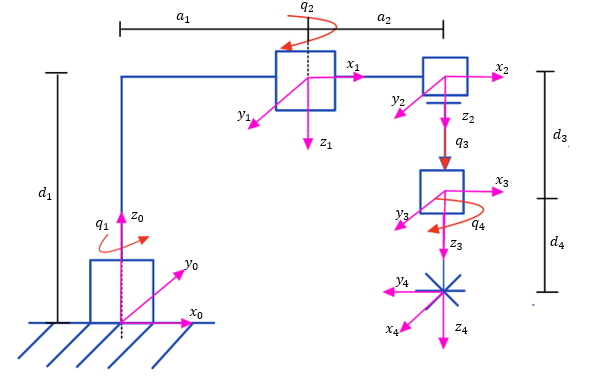

**Figure 4**: Simplified Robot diagram for problem 3

To analyze the system, the homogeneous transformation matrices for the system were calculated using equation 2.66. Like with equations 4a-d, the rotation matrices were calculated by first comparing the frames and then they were  premultiplying the frame rotation matrix by the rotation of the appropriate joint variables in the z direction, equation 2.3. The rotation matrices for the different frames are shown in equations 7a - 7d. Equations 7a, 7b and 7d all have revolute joint variables in them, as the frames associated with those equations all have revolute joints in them. Equation 7c, has no joint variables in it because frame 2 has a prismatic joint and prismatic joints do not cause rotations. 

$R_1^0 =\left\lbrack \begin{array}{ccc}
cq_1  & -sq_1  & 0\\
sq_1  & cq_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & -1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
cq_1  & sq_1  & 0\\
sq_1  & -cq_1  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                         (7a)

$R_2^1 =\left\lbrack \begin{array}{ccc}
cq_2  & -sq_2  & 0\\
sq_2  & cq_2  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
cq_2  & -sq_2  & 0\\
sq_2  & cq_2  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                               (7b)

$R_3^2 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                (7c)

$R_4^3 =\left\lbrack \begin{array}{ccc}
cq_4  & -sq_4  & 0\\
sq_4  & cq_4  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-sq_4  & -cq_4  & 0\\
cq_4  & -sq_4  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                         (7d)

In the same way that the calculation for the position vectors for problem 2 were calculed in equation 5a-5c, the position vectors for the the robot were calculated, see equations 8a-8d.

$d_1^0 =\left\lbrack \begin{array}{c}
a_1 \\
0\\
d_1 
\end{array}\right\rbrack$                                                                                                                                              (8a) 

$d_2^1 =\left\lbrack \begin{array}{c}
a_2 \\
0\\
0
\end{array}\right\rbrack$                                                                                                                                              (8b) 

$d_3^2 =\left\lbrack \begin{array}{c}
0\\
0\\
d_3 +q_3 
\end{array}\right\rbrack$                                                                                                                                       (8c) 

$d_4^3 =\left\lbrack \begin{array}{c}
0\\
0\\
d_4 
\end{array}\right\rbrack$                                                                                                                                              (8d) 

The homogeneous transformation matrices can then be calculated by inputting rotation matrix equation, 7a-7d , the matching postition vector equation, 8a-8d, into equation 2.66, see quations 9a - 9d. 

$H_1^0 =\left\lbrack \begin{array}{cc}
R_1^0  & d_1^0 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                     (9a)             

$H_2^1 =\left\lbrack \begin{array}{cc}
R_2^1  & d_2^1 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                     (9b)     

$H_3^2 =\left\lbrack \begin{array}{cc}
R_3^2  & d_3^2 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                      (9c)    

$H_4^3 \;=\left\lbrack \begin{array}{cc}
R_4^3  & d_4^3 \\
0 & 1
\end{array}\right\rbrack$                                                                                                                                     (9d) 

Similar to in equation 6, the matrices in equation 8a -8d can be post multiplied sequentially to produce the homogeneos tranformation matrix from the base to end effector, $H_4^0$, see equation 10.

$H_4^0 =H_1^0 H_2^1 H_3^2 H_4^3 \;$                                                                                                                                (10)     

In order to calculate the position of the robot with different input angles, the 4th colomn of the tranformation matrix can be extracted. This gives the position vector of the system, see equation 11.

$P_4^0 =$$H_4^0$(:,4)$=\left\lbrack \begin{array}{c}
a_1 +a_2 \,\cos \left(q_1 \right)\\
a_2 \,\sin \left(q_1 \right)\\
d_1 -d_3 -d_4 -q_3 
\end{array}\right\rbrack$                                                                                                      (11)

## Results:

### Problem 1 

To obtain the desired rotation matrix, $R_3^2$,  I first calclated the transpose of  $R_2^0 \;$ and I inputted the appropriate matrices into equation 2. I then used MATLAB to display the correct answer.

clc; clear;
R12= [1 0 0 ;0 1/2 -sqrt(3)/2;0 sqrt(3)/2 1/2]; % given equation
R13= [0 0 -1;0 1 0;1 0 0 ]; % given equation

R21= transpose(R12); % inverse of R12 

R12*R21; % check that R21 is actually R12 ... returns the identity matrix 

% FINAL ANSWER 
R23= R21*R13;

%to check your answer: you can multiply R12 and R23
% your answer should return R13 ... which in this case it does
R12*R23;
R23

R23 =          0         0   -1.0000
    0.8660    0.5000         0
    0.5000   -0.8660         0


### 
$$R_3^2 =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
\frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\
\frac{1}{2} & -\frac{\sqrt{3}}{2} & 0
\end{array}\right\rbrack$$


### Problem 2 

Below are the calculations of the desired homogeneous tranformation matrices, $H_1^0 ,H_2^0 ,H_3^0 \;\mathrm{and}\;H_3^2$.

clc;clear;
% Given link lengths 
l1 = 1;
l2 = 1;
l3 = 1;
l4 = 1;
l5 = 2;
l6 = 0.5; % distance of the cube from o1
l7 = 0.5; % distance of the cube from o1

R01 = [1 0 0; 0 1 0; 0 0 1]; 
R02 = [1 0 0; 0 1 0; 0 0 1];
R03 = [0 1 0; 1 0 0; 0 0 -1];
R20 = transpose(R02);

d01 = [0; l1; 0];
d02 = [-l7; (l1+l6); l4];
d03 = [-l7; (l1+l6); (l4+l5)];
d20 = -d02;

%Final answer 
H01 = [R01 d01; 0 0 0 1]

H01 =      1     0     0     0
     0     1     0     1
     0     0     1     0
     0     0     0     1


H02 = [R02 d02; 0 0 0 1]

H02 =     1.0000         0         0   -0.5000
         0    1.0000         0    1.5000
         0         0    1.0000    1.0000
         0         0         0    1.0000


H03 = [R03 d03; 0 0 0 1]

H03 =          0    1.0000         0   -0.5000
    1.0000         0         0    1.5000
         0         0   -1.0000    3.0000
         0         0         0    1.0000


H20 = [R20 d20; 0 0 0 1];
H23 = H20*H03

H23 =      0     1     0     0
     1     0     0     0
     0     0    -1     2
     0     0     0     1



% you can also check your answer for H23 by forming the HTM by getting R23
% and d23 ... the answer should be the same 
R23 = [0 1 0; 1 0 0; 0 0 -1];
d23 = [0; 0; 2];
check_H23 = [R23 d23; 0 0 0 1];


$$H_1^0 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 1\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_2^0 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & -\frac{1}{2}\\
0 & 1 & 0 & 1\ldotp 5\\
0 & 0 & 1 & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_3^0 =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & -\frac{1}{2}\\
1 & 0 & 0 & 1\ldotp 5\\
0 & 0 & -1 & 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$H_3^2 =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
1 & 0 & 0 & 0\\
0 & 0 & -1 & 2\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


### Problem 3

Problem 3 robot homogeneous tranformation matrix calculation. I then extracted the 4th column of the tranformation matrix and plotted it with the given ranges in order to analyze it's path.

clc; clear;
syms q1 q2 q3 q4 a1 a2 d1 d3 d4

% matrices in terms of degrees 
R01 = [cosd(q1) -sind(q1) 0; sind(q1) cosd(q1) 0; 0 0 1]*[1 0 0; 0 -1 0; 0 0 -1];
R12 = [cosd(q2) -sind(q2) 0; sind(q2) cosd(q2) 0; 0 0 1]*[1 0 0; 0 1 0; 0 0 1];
R23 = [1 0 0; 0 1 0; 0 0 1] * [1 0 0; 0 1 0; 0 0 1];
R34 = [cosd(q4) -sind(q4) 0; sind(q4) cosd(q4) 0; 0 0 1]*[0 -1 0; 1 0 0; 0 0 1];

% Answer in radians 
%R01 = [cos(q1) -sin(q1) 0; sin(q1) cos(q1) 0; 0 0 1]*[1 0 0; 0 -1 0; 0 0 -1];
%R12 = [cos(q2) -sin(q2) 0; sin(q2) cos(q2) 0; 0 0 1]*[1 0 0; 0 1 0; 0 0 1];
%R23 = [1 0 0; 0 1 0; 0 0 1] * [1 0 0; 0 1 0; 0 0 1];
%R34 = [cos(q4) -sin(q4) 0; sin(q4) cos(q4) 0; 0 0 1]*[0 -1 0; 1 0 0; 0 0 1];


d01 = [a1; 0; d1];
d12 = [a2; 0; 0];
d23 = [0; 0; d3+q3];
d34 = [0; 0 ; d4];

H01 = [R01 d01; 0 0 0 1];
H12 = [R12 d12; 0 0 0 1];
H23 = [R23 d23; 0 0 0 1];
H34 = [R34 d34; 0 0 0 1];

% Final answer
H04 = simplify(H01*H12*H23*H34)

$$H04 = \begin{array}{l} \left(\begin{array}{cccc} -\sigma_{2} & \sigma_{1} & 0 & a_{1}+a_{2}\,\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{1} & \sigma_{2} & 0 & a_{2}\,\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ 0 & 0 & -1 & d_{1}-d_{3}-d_{4}-q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\frac{\pi \,\left(q_{2}-q_{1}+q_{4}\right)}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\left(q_{2}-q_{1}+q_{4}\right)}{180}\right) \end{array}$$

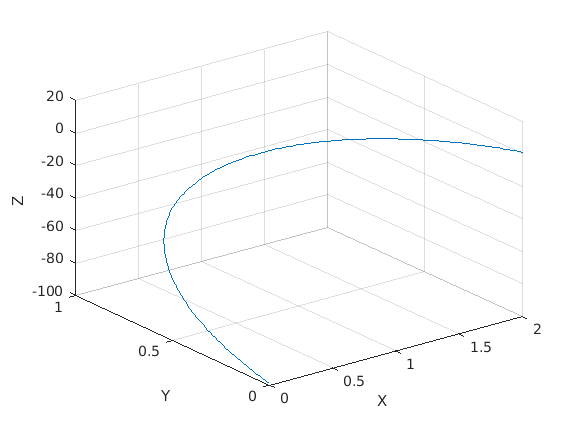


% now to plot my answer 

q1t = 0:1:180; % array to hold joint variable 1
q2t = 0:1/2:90; % array for joint variable 2
q3t = 0:(100/180):100; % array for joint variable 3
q4t = 0:1:180; % array for joint variable 4
% link lengths 
a1t = 1;
a2t = 1;
d1t = 2;
d3t = 0.5;
d4t = 0.5;

pe = expand(H04(1:3,4));
pe_simp = simplify(pe);

x=pe_simp(1);
y=pe_simp(2);
z=pe_simp(3);

x_plot = subs(x,{q1 q2 q3 q4 a1 a2 d1 d3 d4},{q1t q2t q3t q4t a1t a2t d1t d3t d4t});
y_plot = subs(y,{q1 q2 q3 q4 a1 a2 d1 d3 d4},{q1t q2t q3t q4t a1t a2t d1t d3t d4t});
z_plot = subs(z,{q1 q2 q3 q4 a1 a2 d1 d3 d4},{q1t q2t q3t q4t a1t a2t d1t d3t d4t});

plot3(x_plot,y_plot,z_plot)
grid on
xlabel('X ')
ylabel('Y ')
zlabel('Z ')

**Figure 5** - Path of SCARA robot 

## 
$$H_4^0 =\;\left(\begin{array}{cccc}
-\mathrm{sin}\left(q_2 -q_1 +q_4 \right) & -\mathrm{cos}\left(q_2 -q_1 +q_4 \right) & 0 & a_1 +a_2 \,\mathrm{cos}\left(q_1 \right)\\
-\mathrm{cos}\left(q_2 -q_1 +q_4 \right) & \mathrm{sin}\left(q_2 -q_1 +q_4 \right) & 0 & a_2 \,\mathrm{sin}\left(q_1 \right)\\
0 & 0 & -1 & d_1 -d_3 -d_4 -q_3 \\
0 & 0 & 0 & 1
\end{array}\right)$$


## Discussion:

### Problem 1 

The first problem of this assignment, implementing the rules of composition of rotations. Knowing these rules, it was very simple to figure out the correct matrix multiplication in order to obtain the desired rotation matrix. 

### Problem 2 

The second problem of this assignment was very interesting. It involved analyzing a system that was composed of many parts ( a robot, table, camera and cube), and obtaining a homogeneous transformation matrices for the system. Once I calculated the homogeneous transformation matrices for the syste, I was able to check my work for errors, using equation 6. After calculating the tranformation matrices using equation 2.66, I was able to reproduce the the same homogeneous matrix that represents the tranformation of frame 3 with respect to frame 2, $H_3^2$, using equation 6. The fact that the matrices match show that my calculations was probably correct.

### Problem 3

The third problem of this assignment was my favorite as it allowed me to look into and learn more about the SCARA manipulator robot. This problem involved analyze and creating a simplified model of the robot. The robot in this problem was a four degree of freedom robot. Three of its joints were revolute and one was prismatic. To analyze this robot I calculated the successive rotation matrices and postion vectors for each frame and then used them to calculate the homogenouse rotation matrix from the base of the robot to the end effector. I then extracted the position vector from the tranformation matrix and plotted it with the given joint values. Figure 5, displays the resulting plot. The plot displays postion of the end effector relative to the base. The base of the robot is fixed, the joints of the robot cause the end effector's position to change. The plot looks as expected; The robot's endeffector is steadily increasing in height as the interval of the prismatic joint increases from 0 to 100 mm. Also the angles of the the other three angles increase incrementally too, so the trajectory of the end effector on the plot, seems to make sense.  

### References:

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.